# Epidemia desatada

Se ha informado sobre el inicio de una epidemia de coronavirus en la ciudad. ¡Alrededor de 100 mil personas están en riesgo!

Los pronósticos de los investigadores se muestran a continuación: 

S(t) son las personas susceptibles de contraer la enfermedad, I(t) son los infecciosos, R(t) son los recuperados y C(t) son los costos de la enfermedad para el estado.

clear;clc;close all
func='SIRSemillero'; %Nombre del archivo del modelo
ranges=[8e4 1e5;0 100; 0 500; 0.01 0.5; 0.01 0.2; 0.01 0.2; 1 1000; 1 1000; 0 1]; %Intervalos para los parámetros del modelo
names = {'S_0','I_0','R_0','\beta','\gamma','\alpha', 'Init', 'End', 'V'}; %Nombres de los parámetros del modelo
out_names = {'S(t)','I(t)','R(t)', 'C(t)'}; %Nombres de las salidas del modelo
nominal=[1e5,10,100,0.21,0.05,0.01, 1, 1000, 0]; %valores de simulación nominal (no es necesario)
domain=[0, 500];%Dominio de simulación
copt = struct; %Se transforma en in al interior del modelo
copt.vccCost = 1e5;
copt.ICost = 1e6;
T = gsua_dataprep(func,ranges,'domain',domain,'names',names,'out_names',out_names,'nominal',nominal,'opt',copt);

Setting environment to work with user-defined function


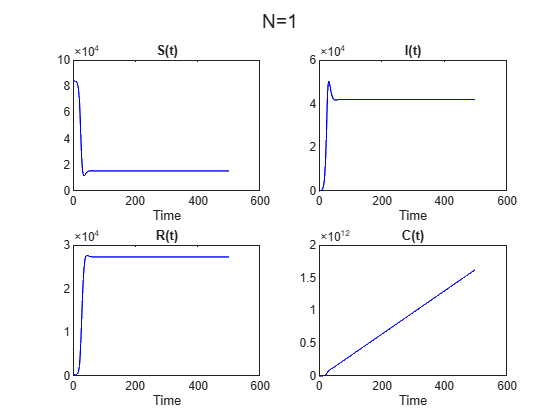

Progress: 100.0 %


 
escenario = gsua_dmatrix(T,1)';
T.Nominal(1:6) = escenario(1:6);
figure(1)
clf
Yprev = gsua_eval(T.Nominal,T);

M = gsua_dmatrix(T,500);
T.Properties.CustomProperties.output = [2,4];

A continuación los investigadores han revelado analíticas sobre la dinámica de la enfermedad

### Análisis de incertidumbre

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 2:26:29
Number of simulations: 500


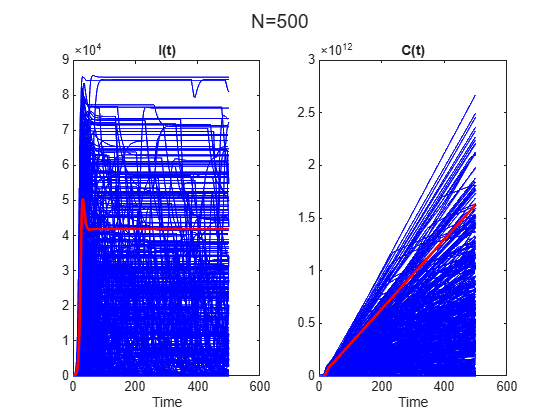

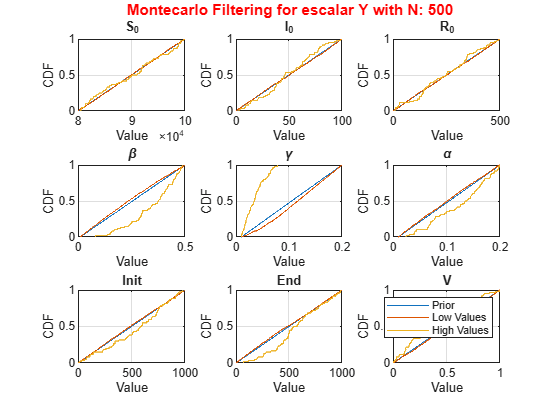

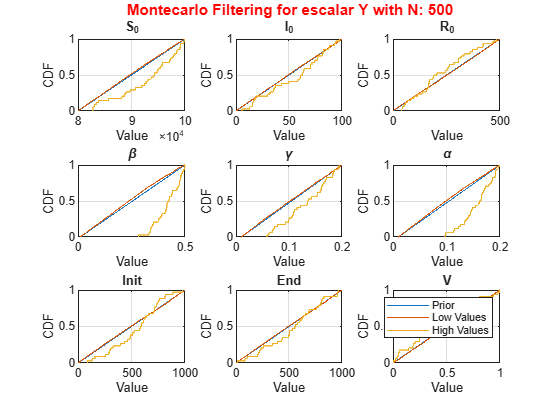

 
Y = gsua_ua(M,T,'parallel',false);

### Análisis de sensibilidad para personas infectadas

 
M = gsua_dmatrix(T,5000);
T.Properties.CustomProperties.output = 2;
T_sa = gsua_sa(M,T,'parallel',false);

Progress: 10%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:7
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 2:45:59
Number of simulations: 27500
Progress: 19%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:6
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 2:45:59
Number of simulations: 27500
Progress: 28%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:6
Elapsed time (h:m:s): 0:0:2
Estimated stop time (h:m:s): 2:45:59
Number of simulations: 27500
Progress: 37%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:5
Elapsed time (h:m:s): 0:0:3
Estimated stop time (h:m:s): 2:45:59
Number of simulations: 27500
Progress: 46%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:4
Elapsed time (h:m:s): 0:0:3
Estimated stop time (h:m:s): 2:45:59
Number of simulations: 27500
Progress: 55%
Estimated processing time (h:m:s): 0:0:8
Remaining time (h:m:s): 0:0:3
Elapsed time (h:m:s)

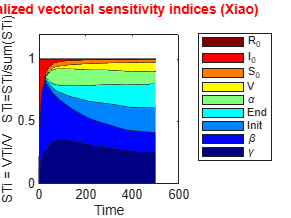

figure(2)
clf
gsua_plot('TotalSensitivityArea',T_sa,T_sa.STi_vec,0:500)

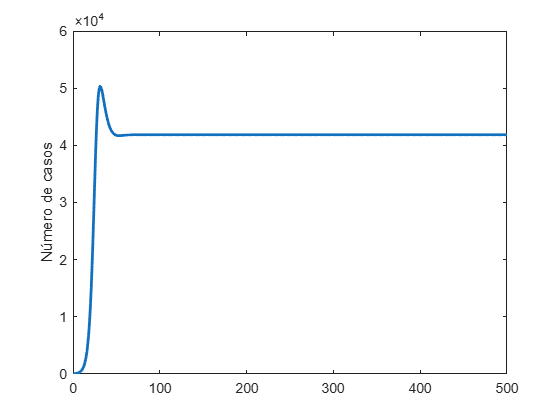

figure(3)
clf
plot(0:500,Yprev(1,:,2),'LineWidth',2)
ylabel("Número de casos")

## Planea una estrategia para minimizar personas enfermas y costos

El equipo técnico informa que cada persona enferma le cuesta al sistema de salud 1 millón de pesos. Adicionalmente, existe una vacuna que previene la enfermedad y tiene un costo de 100 mil pesos por aplicación, aunque su efecto se va perdiendo en el tiempo. El alcalde de la ciudad le pide abaratar los costos asociados a la enfermedad. Para ello, es posible planear un plan de vacunación con la duración que usted elija y que permite vacunar hasta el 10% de la población susceptible. Adicionalmente, es posible modificar un parámetro asociado a la epidemia destinando recursos públicos a distintos fines (campañas, cuarentenas, aislamiento de personas, etc...), pero solo es posible modificar uno de los parámetros por cierto porcentaje dado que solo se puede hacer una intervención.

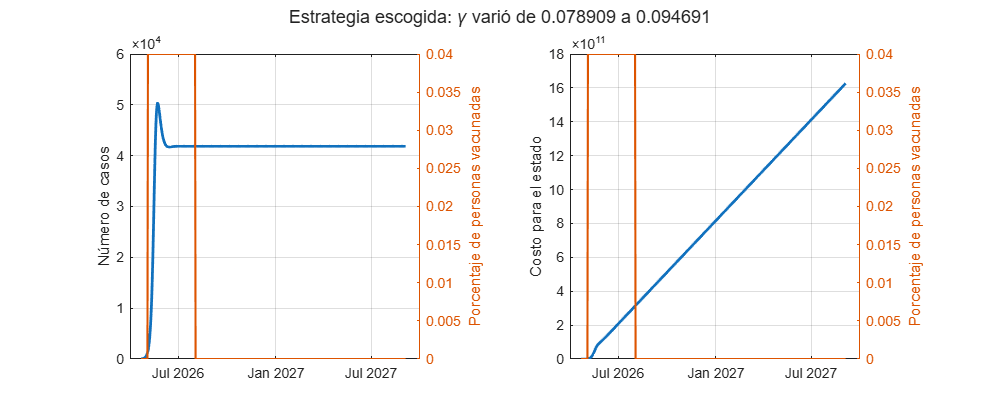

dates = [14 103];
percentageVcc = 0.04;
R0 = 100;
I0 = 100;
S0 = 100;
alpha = 100;
beta = 100;
gamma = 120;
 

nom = T.Nominal;
nom(7:9) = [dates(1),dates(2),percentageVcc]';
nom(1:6) = nom(1:6).*([S0 I0 R0 beta gamma alpha]/100)'; 
vacStrat = zeros(1,501);
vacStrat(dates(1):dates(2)) = percentageVcc;
time = datetime("now") + days(0:500);

detect = nom(1:6) ~= T.Nominal(1:6);

f = figure(4);
clf
f.Position = [10 10 1000 400];
subplot(1,2,1)
plot(time,Yprev(1,:,2),'LineWidth',2)
ylabel("Número de casos")
yyaxis right
plot(time,vacStrat,'LineWidth',1.5)
ylabel("Porcentaje de personas vacunadas")
grid on

subplot(1,2,2)
plot(time,Yprev(1,:,4),'LineWidth',2)
ylabel("Costo para el estado")
yyaxis right
plot(time,vacStrat,'LineWidth',1.5)
ylabel("Porcentaje de personas vacunadas")
grid on
sgtitle("Estrategia escogida: "+ T.Properties.RowNames(detect) + " varió de " +num2str(T.Nominal(detect)) + " a " + num2str(nom(detect)))

#### Es hora de aplicar la estrategia ¡buena suerte!

 
T.Properties.CustomProperties.output = 1:4;
Y_new = gsua_eval(nom,T,[],[],false,false);

Progress: 100.0 %


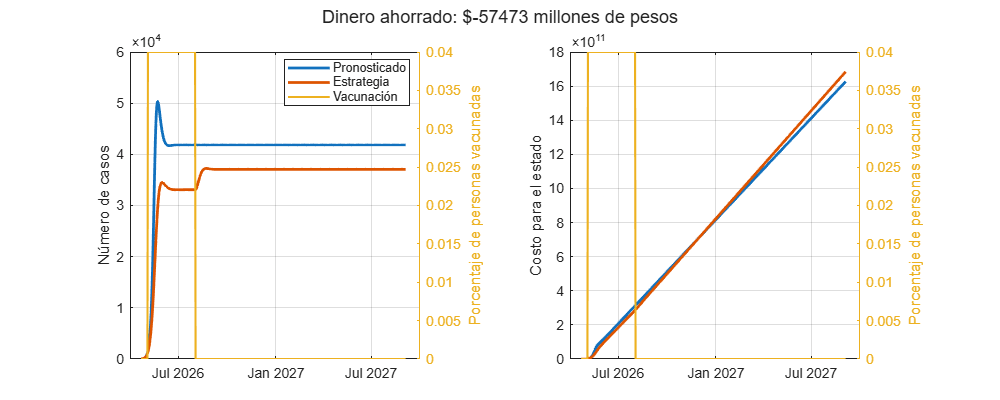

f = figure(5);
clf
f.Position = [10 10 1000 400];
subplot(1,2,1)
plot(time,Yprev(1,:,2),'LineWidth',2)
ylabel("Número de casos")
hold on
plot(time,Y_new(1,:,2),'LineWidth',2)
yyaxis right
plot(time,vacStrat,'LineWidth',1.5)
ylabel("Porcentaje de personas vacunadas")
grid on
legend(["Pronosticado","Estrategia", "Vacunación"],'Location','best')

subplot(1,2,2)
plot(time,Yprev(1,:,4),'LineWidth',2)
ylabel("Costo para el estado")
hold on
plot(time,Y_new(1,:,4),'LineWidth',2)
yyaxis right
plot(time,vacStrat,'LineWidth',1.5)
ylabel("Porcentaje de personas vacunadas")
grid on
sgtitle("Dinero ahorrado: $"+ num2str(round((Yprev(1,end,4)-Y_new(1,end,4))/1e6)) + " millones de pesos")